% 1. Ábra előkészítése
figure('Name', 'Path tervező', 'NumberTitle', 'off');
axis([0 100 0 100]); 
grid on; hold on;
xlabel('X koordináta [m]'); ylabel('Y koordináta [m]');
title('Kattints a kanyarok CSÚCSAINAK lerakásához! (Befejezés: ENTER)');

% Kezdeti üres vektorok
x_coords = [];
y_coords = [];

% "Élő" vonal: ez most a pálya "külső széle" lesz, amiben a sarkok vannak
h_raw_plot = plot(nan, nan, '--k', 'LineWidth', 1, 'Marker', 'o', 'MarkerFaceColor', 'y', 'DisplayName', 'Kattintott (Külső) Ív');

disp('Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.');

Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.



% 2. Interaktív kattintós ciklus
while true
    [x_new, y_new, ~] = ginput(1);
    if isempty(x_new), break; end

    x_coords = [x_coords; x_new];
    y_coords = [y_coords; y_new];

    set(h_raw_plot, 'XData', x_coords, 'YData', y_coords);
    drawnow;
end

% 3. Ideális ív (Racing Line) generálása
if numel(x_coords) >= 3
    disp('Számolás: Pálya generálás...');

    % Zárjuk be a vonalat
    x_coords = [x_coords; x_coords(1)];
    y_coords = [y_coords; y_coords(1)];

    % Fizikai távolságok kiszámítása
    distances = sqrt(diff(x_coords).^2 + diff(y_coords).^2);
    t = [0; cumsum(distances)]; 

    % 1. LÉPÉS: Nagyon sűrű "nyers" szögletes vonal (10 cm-es felbontás)
    t_finom = 0:0.1:t(end); 
    x_lin = interp1(t, x_coords, t_finom, 'linear');
    y_lin = interp1(t, y_coords, t_finom, 'linear');
end

Számolás: Pálya generálás...


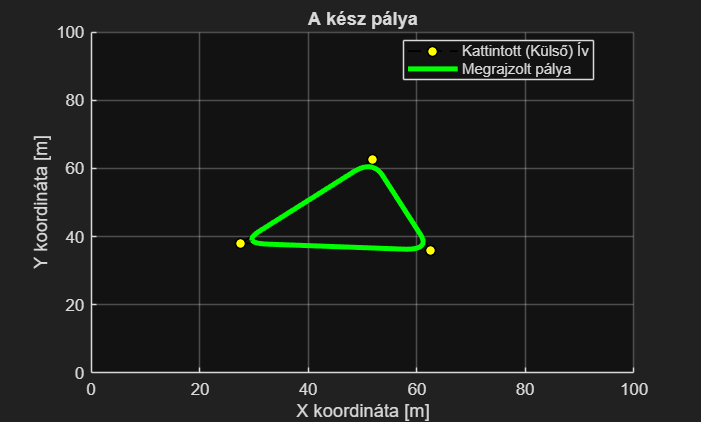

    % 2. LÉPÉS: A szűrési ablak mérete (Ez határozza meg, mennyire vágja le a kanyart!)
    % 100-as ablak 10 cm-es felbontásnál kb. 10 méteres kanyarsugarat jelent.
    % Ezt az értéket nyugodtan állíthatod (pl. 50-től 200-ig), ha élesebb vagy laposabb kanyart akarsz!
    ablak = 100; 

    % 3. LÉPÉS: Zárt hurok pufferelése (hogy a start/cél vonalnál is sima legyen a kanyar)
    x_pad = [x_lin(end-ablak:end-1), x_lin, x_lin(2:ablak+1)];
    y_pad = [y_lin(end-ablak:end-1), y_lin, y_lin(2:ablak+1)];

    % 4. LÉPÉS: Mozgóátlag szűrő (ez vágja le a csúcsokat F1-es stílusban)
    x_sm = movmean(x_pad, ablak);
    y_sm = movmean(y_pad, ablak);

    % Visszavágás az eredeti méretre
    x_smooth = x_sm(ablak+1 : end-ablak);
    y_smooth = y_sm(ablak+1 : end-ablak);

    smooth_path = [x_smooth', y_smooth'];

    % 4. Kirajzoljuk a végeredményt
    set(h_raw_plot, 'XData', x_coords, 'YData', y_coords); 
    plot(x_smooth, y_smooth, '-g', 'LineWidth', 3, 'DisplayName', 'Megrajzolt pálya');
    legend('Location', 'best');
    title('A kész pálya');

    disp('Figyelem: Legalább 3 pont kell!');

Figyelem: Legalább 3 pont kell!
